# HW4 Q2

(a) Dynamic Decoupling. Find a proper approximation to G−1. Use this to design a dynamic decoupling-based controller that achieves (approximately) loop shapes of L = 100/s for each of the diagonal elements. Form the loop transfer function L = GK and use the margin command to show the performance of L(1,1) and plot the Bode magnitude of the 2x2 sensitivity function.

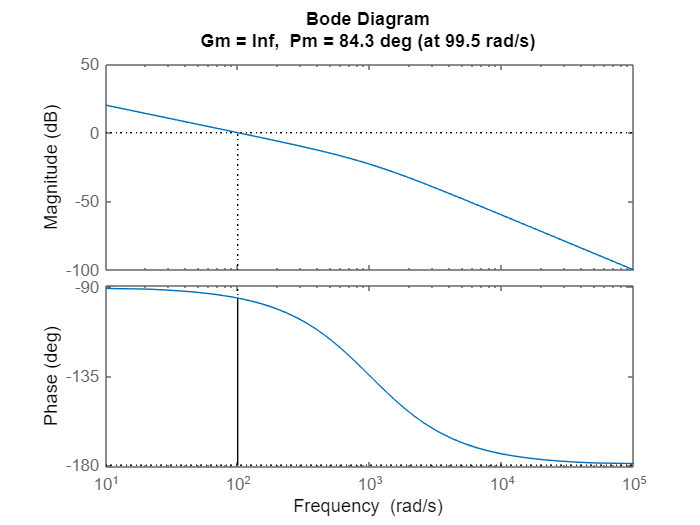

s = tf('s');
G = [10*(s+2)/(s^2+0.2*s+100) 1/(s+5);(s+2)/(s^2+0.1*s+10) 5*(s+1)/(s+2)/(s+3)];
Ginv = inv(G)*1000/(s+1000)*eye(2);
K_inv = Ginv*[100/s 0;0 100/s];
L_inv = minreal(G*K_inv, 0.5);
T_inv = feedback(L_inv, eye(2));
S_inv = eye(2)-T_inv;
margin(L_inv(1,1))

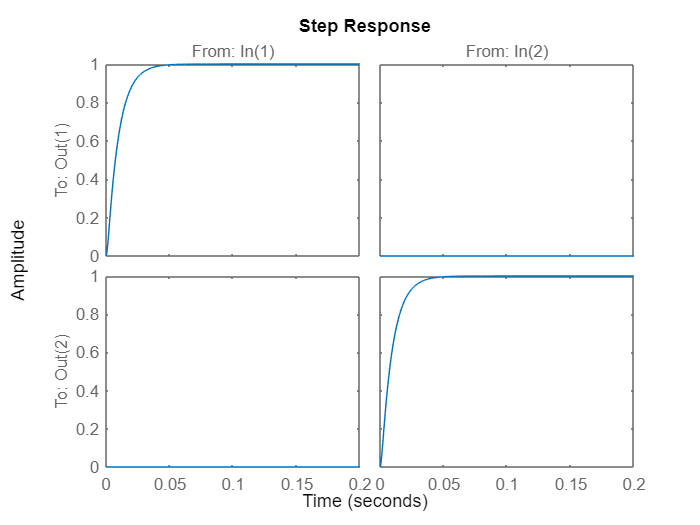

step(T_inv,0.2)

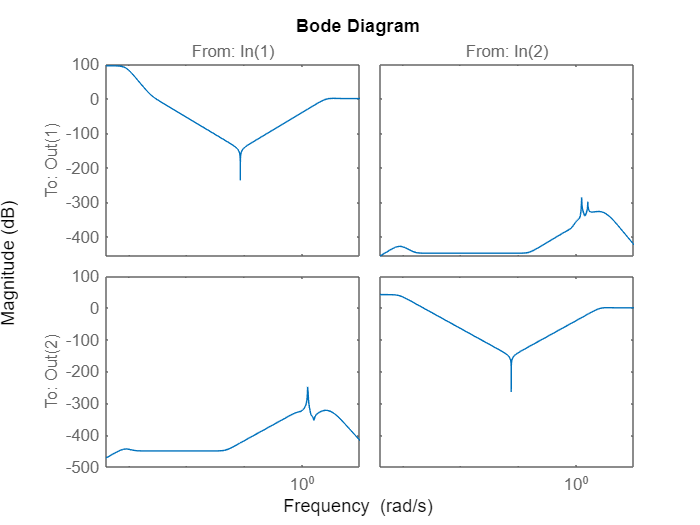

bodemag(S_inv)

(b) Mixed Sensitivity Synthesis. Using first order weights for Wp and WT and a constant actuator weight corresponding to a maximum control usage of 100 at each input, design a mixed sensitivity controller that

• Maximizes the bandwidth such that γ < 1.

• Rejects steady state disturbances by a factor of 1000

• Rejects high frequency noise by a factor of 1000

• Has a sensitivity peak of no more than 2 and a complementary sensitivity peak of no more than 1.5

• Has a complementary sensitivity crossover frequency at most 3x the sensitivity crossover frequency.

Plot the magnitudes of WpS, WtT, and WuKS for your final design.

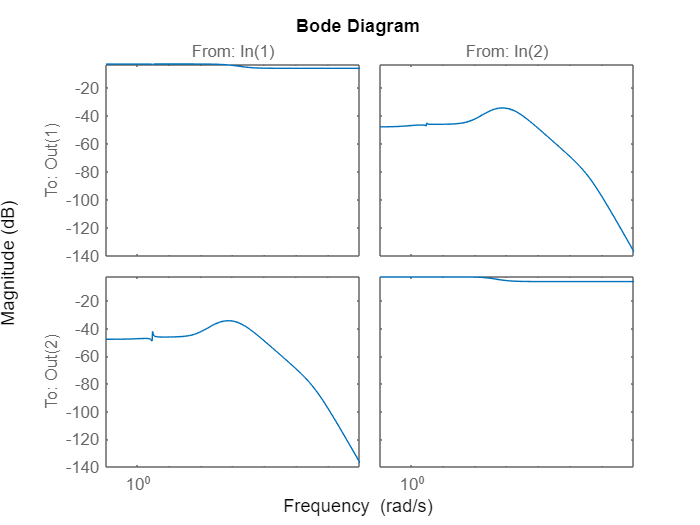

s = tf('s');
G = [10*(s+2)/(s^2+0.2*s+100) 1/(s+5); (s+2)/(s^2+0.1*s+10) 5*(s+1)/(s+2)/(s+3)]; %2x2 matrix
M = 2;  % Maximum sensitivity peak
A = 1000;  % Steady state disturbance attenuation
Mt = 1.5;  % Maximum complementary sensitivity peak
At = 0.001;  % High frequency noise attenuation 
GAM = 0;  % Dummy value to start
BW = 10; % Trivial low value for bandwidth
BW_step = 5;
Wp = [0 0; 0 0]; % Performance weight
Wu = [1/100 0; 0 1/100];
K = [0 0;0 0];
while GAM<1
    Wp_old = Wp;
    Wt_old = Wt;
    Wp = [((s/M)+BW)/(s+BW/A) 0; 0 ((s/M)+BW)/(s+BW/A)];
    Wt = makeweight(1/Mt,3*BW,1/At) * eye(2,2);  %The 3x bandwidth is to give some separation between the requirements
    K_old = K;
    [K,CL,GAM,info] = mixsyn(G,Wp,Wu,Wt);  %This is the magic synthesis command.  Much of this class is about how and why this works.  NOTE:  For comparison to loopsyn below, be sure to use [],[] for 2nd two arguments.
    BW = BW+BW_step;  %Bisection would be cleaner, but this works!
end
L_ms = G * K_old;
S_ms = inv(eye(2,2)+L_ms);
T_ms = eye(2,2) - S_ms;
figure
% bodemag(inv(Wp_old),S_ms) %Compare with performance
bodemag(Wp_old * S_ms) %Compare with performance

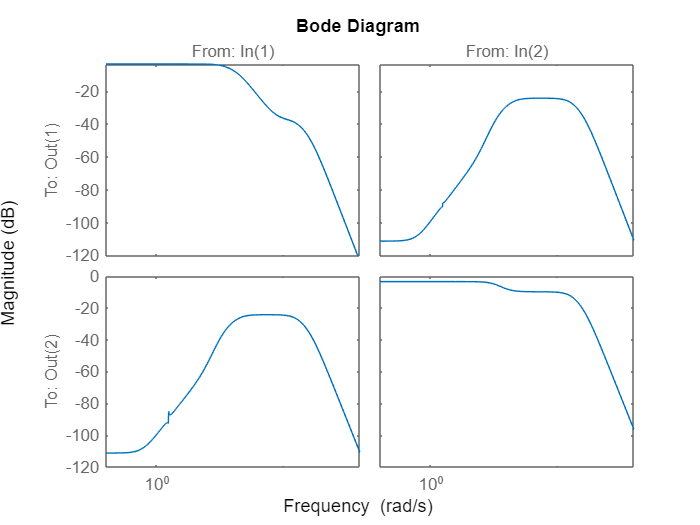

% legend('1/Wp','S_{ms}','location', 'SouthEast')
%legend('WpS','location', 'SouthEast')
figure
bodemag(Wt*T_ms); %Compare with control robustness

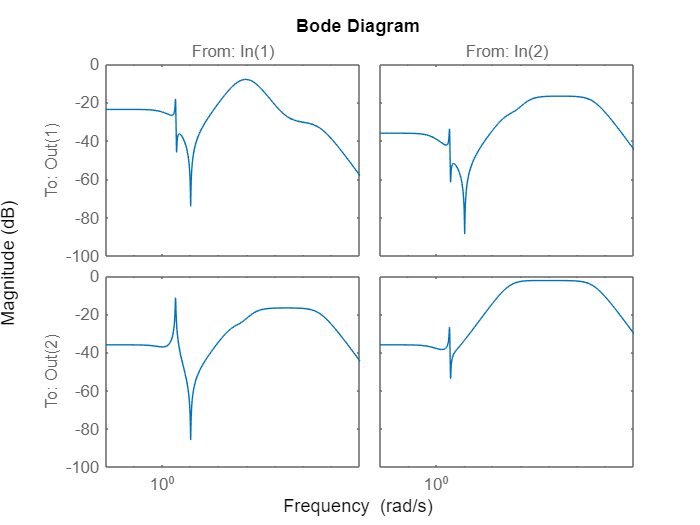

figure
bodemag(Wu*K_old*S_ms);

# HW4 Q3

(a) For the block diagram shown below: (1) Find the generalized plant P, and (2) Find N = Fl(P,K). For simplicity, feel free to give the system inside the dashed line a name - say G⋆.

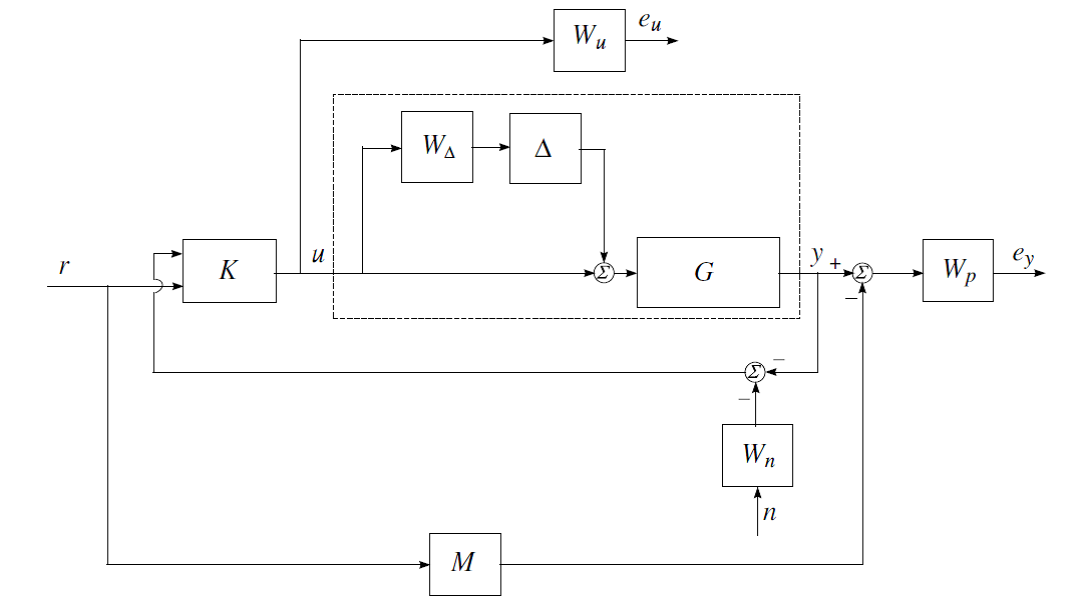

(b) Use the Matlab command sysic to generate the generalized plant for the mixed sensitivity problem in Problem 2.b. NOTE: Use the block diagram from class - it is very different from the one in 3.a. Run the command K = hinfsyn(P,2,2) for your generalized plant and compare the controller to the one you found in Problem 2.b (Bode Plot). Now the *sysic* command expects us to define three variables as follows.  *systemnames* includes the names of the transfer functions that make up the system.  They must be separated by spaces if there are more than 1.

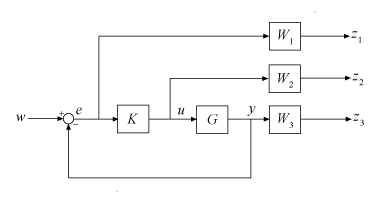

systemnames = 'G Wp Wu Wt'; %Block name only

Now we have to define the inputs and outputs to the system by giving values to *inputvar* and *outputvar*.

inputvar = '[r{2};u{2}]';
outputvar = '[Wp;Wu;Wt;r-G]'; %Strangely, the system outputs are just the name

Here the variables are partitioned as before, i.e. the input variables are listed as $[w ,u]^T$.  Now we need to give the inputs to each system.

input_to_G = '[u]';
input_to_Wp = '[r-G]';
input_to_Wu = '[u]';
input_to_Wt = '[G]';

That's the requirements!  Now we put it in action.

cleanupsysic = 'yes';  %This drops all the useless variables from workspace
P = sysic

P =
 
  A = 
                x1          x2          x3          x4          x5          x6          x7          x8          x9         x10         x11
   x1         -0.2       -12.5           0           0           0           0           0           0           0           0           0
   x2            8           0           0           0           0           0           0           0           0           0           0
   x3            0           0        -0.1        -2.5           0           0           0           0           0           0           0
   x4            0           0           4           0           0           0           0           0           0           0           0
   x5            0           0           0           0          -5           0           0           0           0           0           0
   x6            0           0           0           0           0          -5          -3           0           0           0           0
   x7         

Now let's test to see that it worked...

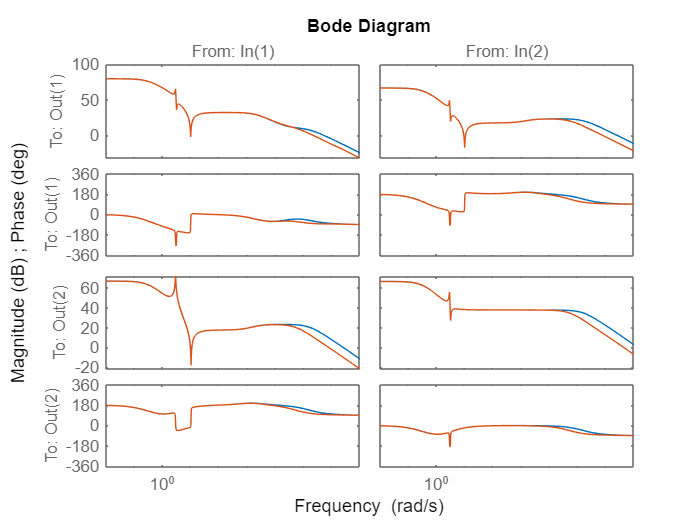

[Kms,CL,GAM] = mixsyn(G,Wp_old,Wu,Wt);
[Khinf,CL,GAM] = hinfsyn(P,2,2);
bode(Kms,Khinf)  %They're on top!